# Simulations with Kuramoto model of cell cycle and metabolic oscillators 

*Serdar Ozsezen*

*11th June 2019*

This live script contains the simulations performed with parameters we estimated for the model. 

First we will load the estimated parameter sets, phase differences and metabolic frequencies.

load ../parray.mat;

There are 18 parameter sets and 5 different nutrient conditions. Each row in `parray` corresponds to an estimated set of parameters, phase differences and frequencies. 

% Indices of natural metabolic frequencies 
wmet_index = [2 7 12 17 22];

% Indices of phase differnces 
theta_index = [3 4 5; 8 9 10; 13 14 15; 18 19 20; 23 24 25];

% Simulation time
dt = 0.1;
tspan = 0:dt:1000;

% Results 
thetas_r = zeros(10001,4,18,5);

Here we will integrate all 18 parameter sets for all nutrient conditions.

for i = 1:18 % Iterate parameter sets
    
    % Select one parameter set 
    pars = parray(i,:);
    
    % Prepare the input parameters 
    input_pars = zeros(1,16);
    
    % Natural cell cycle frequencies and coupling constants
    input_pars(2:16) = pars(26:40);
    
    for j = 1:5 % Iterate nutrient conditions
        
        % Natural metabolic frequency
        input_pars(1) = pars(wmet_index(j));
        
        % Initial values (phases) for integration 
        % Order is Metabolism, START, S, M
        theta0 = zeros(1,4);
        theta0(2:4) = pars(theta_index(j,:));
        
        % Integrate 
        [t,thetas] = ode15s(@(t,th)kuramoto(t,th,input_pars),tspan,theta0);
        thetas_r(:,:,i,j) = thetas;
    end
    
end

Here we will plot the results of the simulations. For convenience we will only plot the results from best fitting parameter set. 

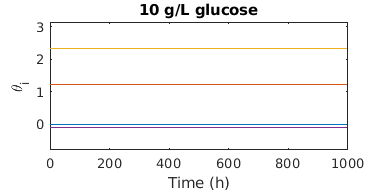

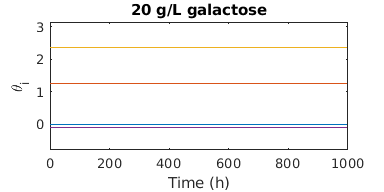

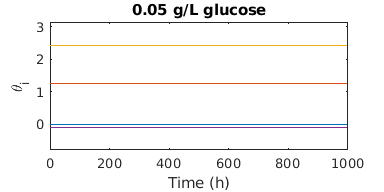

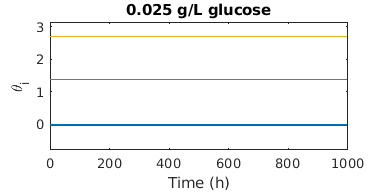

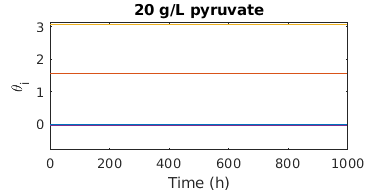

% Calculate phases with respect to metabolism
theta = zeros(size(thetas_r));
theta(:,2,:,:) = thetas_r(:,2,:,:) - thetas_r(:,1,:,:);
theta(:,3,:,:) = thetas_r(:,3,:,:) - thetas_r(:,1,:,:);
theta(:,4,:,:) = thetas_r(:,4,:,:) - thetas_r(:,1,:,:);

conditions = {'10 g/L glucose', '20 g/L galactose','0.05 g/L glucose', '0.025 g/L glucose', '20 g/L pyruvate'};

for i = 1:5
    
    % Fifth is the best fitting parameter set
    figure();
    plot(t,theta(:,:,5,i));
    
    % legend({'MET','START','S','M'});
    set(gcf, 'units', 'inches');
    set(gcf, 'position', [0 0 4 2]);
    ylim([-pi/4 pi]);
    xlabel('Time (h)');
    ylabel('\theta_i');
    title(conditions(i));
end